# Ex 3-3: SURF feature detection (Demo)

## Clean up environment

clc             % Clear console
clear variables % Clear workspace
close all       % Close figures

## Parameters

% TODO: Run the algorithm on images from the library.
% - box, basmati y book vs. scene
% - cocacola vs. cocacolas
% - object1, object2, object3 vs. image_test1, image_test2
% - car_smart1, car_smart2, car_smart3 (convert to grayscale before use)

% Reference pairs (by row)
refPair = [
    "DemoPratFullAltMicro.png", "DemoPratFullAlt.png";
    %"box.pgm", "scene.pgm";           % 1
    %"basmati.pgm", "scene.pgm";       % 2
    %"book.pgm", "scene.pgm";          % 3
    %"cocacola.pgm", "cocacolas.pgm";  % 4
    %"object1.pgm", "image_test1.pgm"; % 5
    %"object1.pgm", "image_test2.pgm"; % 6
    %"object2.pgm", "image_test1.pgm"; % 7
    %"object2.pgm", "image_test2.pgm"; % 8
    %"object3.pgm", "image_test1.pgm"; % 9
    %"object3.pgm", "image_test2.pgm"; % 10
    %"car_smart1.jpg", "car_smart2.jpg"; % 11
    %"car_smart1.jpg", "car_smart3.jpg"; % 12
    %"car_smart2.jpg", "car_smart3.jpg"; % 13
    ];

## Loop begin

for row = 1:size(refPair, 1)

## Pre-process image

% Load images and convert to grayscale if RGB
I1 = im2gray(imread(refPair(row, 1)));
I2 = im2gray(imread(refPair(row, 2)));

## Compute SURF features

% Find SURF features
points1 = detectSURFFeatures(I1);
points2 = detectSURFFeatures(I2);

% Extract features
[f1,vpts1] = extractFeatures(I1,points1);
[f2,vpts2] = extractFeatures(I2,points2);

## Match features

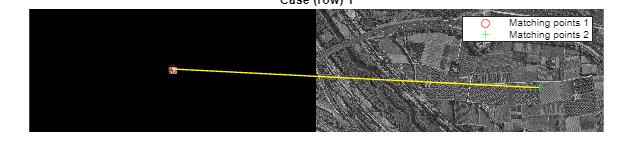

% Find matching features
indexPairs = matchFeatures(f1,f2);

% Find matching points.
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

% Plot points
figure
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, 'montage'),
legend('Matching points 1','Matching points 2'), title("Case (row) " + string(row));

## Loop end

end